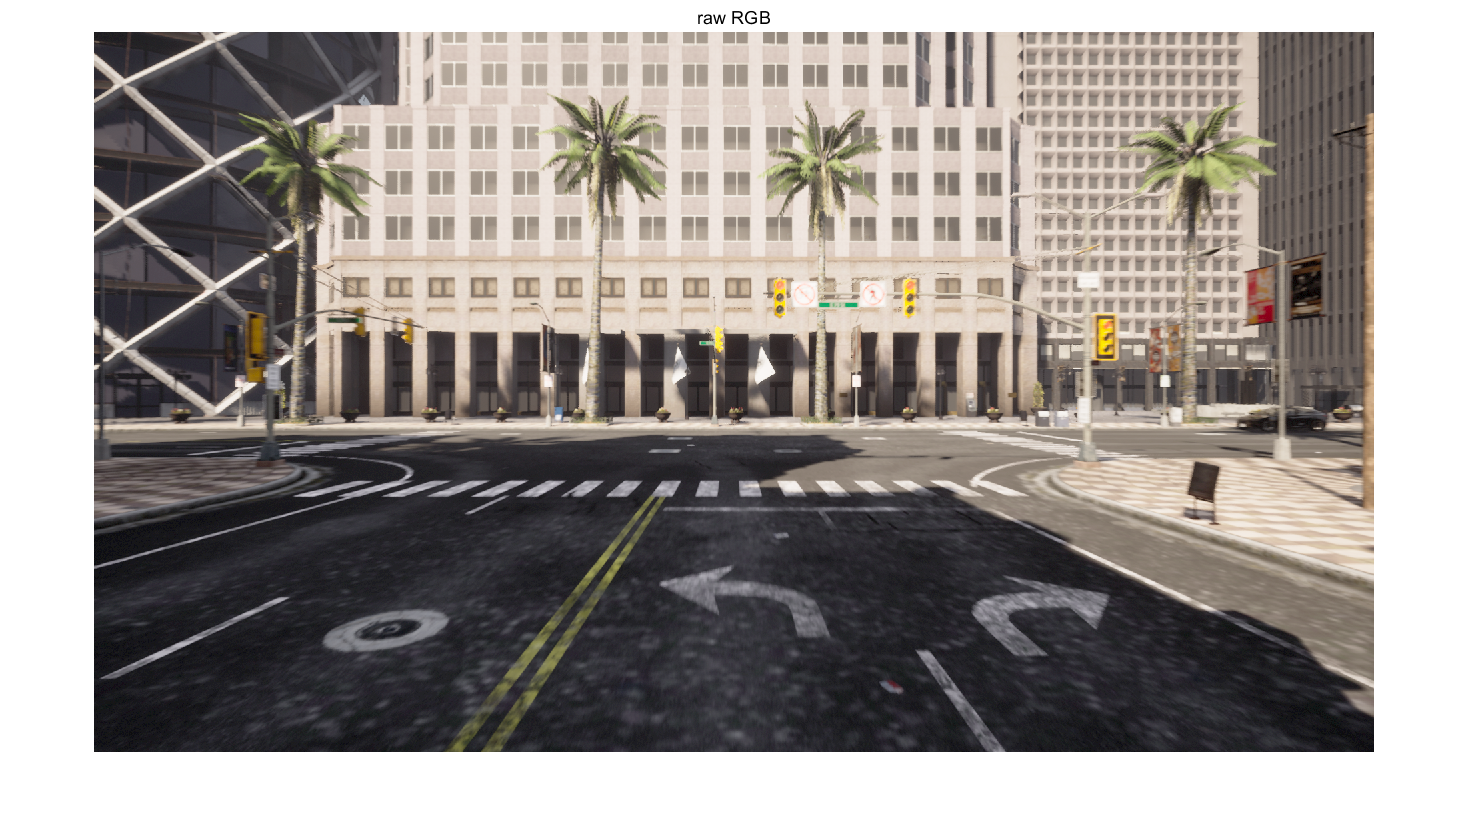

clear; close all; clc;

% hyper params
theta = 0;  % degree  0 / 5

pic_num = 60;  %t10_s0_r0的img在20之后h=2.4m

% path = 'C:/dataset/CARLA/t10_s0_r'+num2str(theta);
path = "E:/Program Files/dataset/CARLA/t10_s0_r"+num2str(theta);
original_img_path = path+'/rgb/000000'+num2str(pic_num)+'.png';
optical_flow_path = path+'/optical_flow/000000'+num2str(pic_num)+'.tif';
optical_flow_path_png = path+'/optical_flow/000000'+num2str(pic_num)+'.png';
semantic_path = path + '/semantic/000000'+num2str(pic_num)+'.png';
depth_path = path + '/depth/000000'+num2str(pic_num)+'.png';

% 图1 原始RGB
rgb_img = imread(original_img_path);
fig1 = figure;
imshow(rgb_img)
title("raw RGB")
axis off

addToolbarExplorationButtons(gcf)
    

% 图2 光流图

% optical_flow_img = imread(optical_flow_path);

% flow_u = (double(optical_flow_img(:,:,1))-2^15)/64.0;
% flow_v = (double(optical_flow_img(:,:,2))-2^15)/64.0;
% flow_valid = optical_flow_img(:,:,3);
% flow_u(flow_valid==0) = nan;
% flow_v(flow_valid==0) = nan;
% 
% fig2 = figure;
% subplot(2,1,1); imshow(flow_u, [], 'Colormap', jet(4096));title("original fu")
% subplot(2,1,2); imshow(flow_v, [], 'Colormap', jet(4096));title("original fv")
% 
% addToolbarExplorationButtons(gcf)
    

% 获取路面的mask 
semantic_img = imread(semantic_path);
%imshow(semantic_img)
% road: (128,64,128)
% road line: (157, 234, 50)
mask_road=zeros(size(semantic_img,1),size(semantic_img,2),"int8");
mask_roadline=zeros(size(semantic_img,1),size(semantic_img,2),"int8");
for i = 1 : size(semantic_img,1)
    for j = 1 : size(semantic_img,2)
        if semantic_img(i,j,1)==128 ...
            && semantic_img(i,j,2)==64 ...
            && semantic_img(i,j,3)==128
            mask_road(i,j)=1;
        end
        if semantic_img(i,j,1)==157 ...
            && semantic_img(i,j,2)==234 ...
            && semantic_img(i,j,3)==50
            mask_road(i,j)=1;
        end
    end
end

mask = mask_road | mask_roadline;

mask = single(mask);


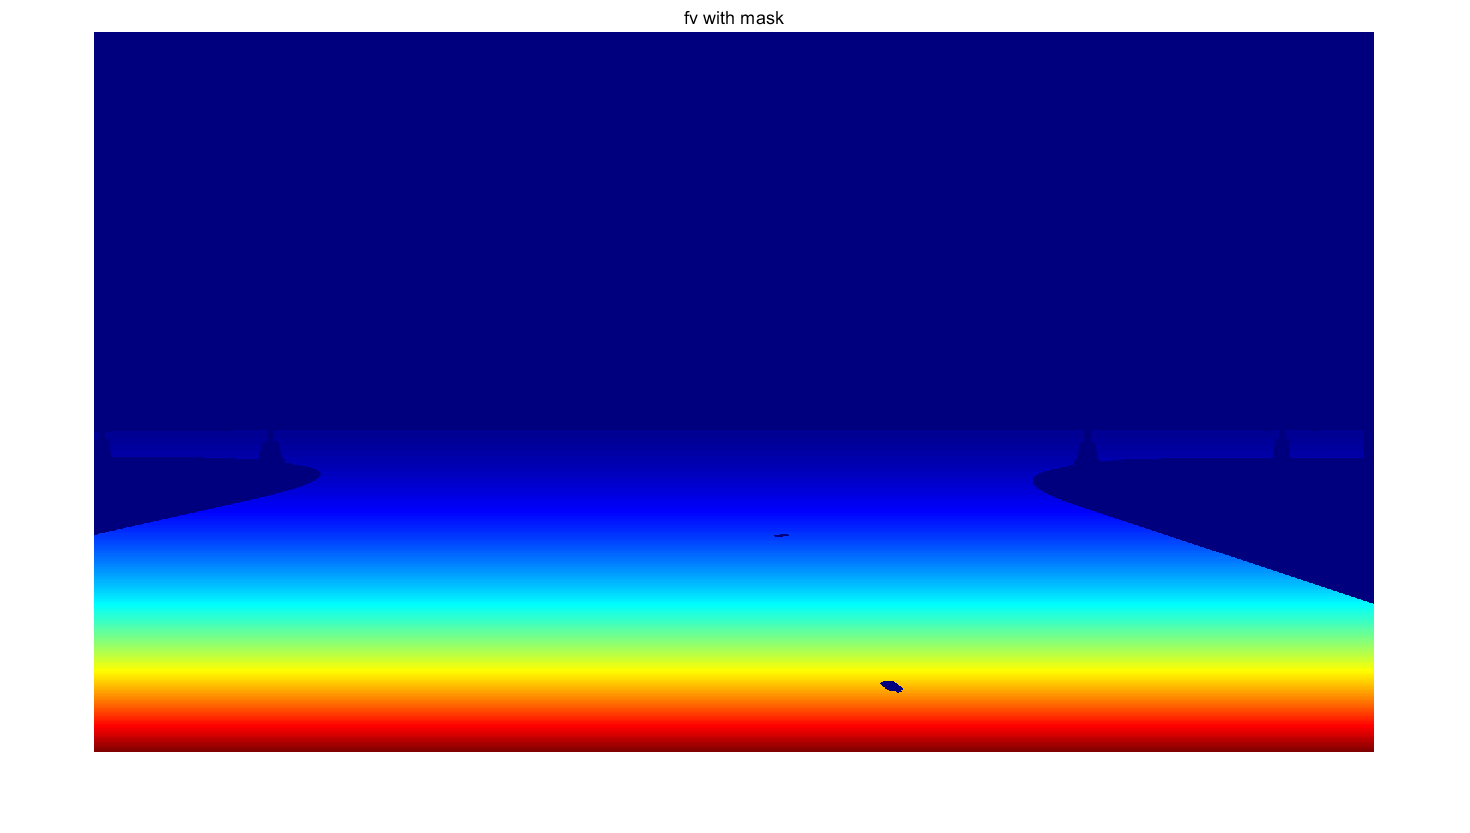

%图3 光流fv图带掩码 

image_h = 1080; 
image_w = 1920;

flow_u=ones(1,image_h*image_w);
flow_v=ones(1,image_h*image_w);
flow_img_origin = imread(optical_flow_path);
for i =1:size(flow_img_origin,2)/2
    flow_u(i)=flow_img_origin(2*i-1);
    flow_v(i)=flow_img_origin(2*i);
end

flow_u= reshape(flow_u, image_w, image_h);
flow_u=flow_u';
flow_v= reshape(flow_v, image_w, image_h);
flow_v=flow_v';

% flow_img = reshape(flow_img, 1080, 1920, 2);
% flow_img=flow_img'
% 
% CH0 = flow_img(:, :, 2);
% CH1 = flow_img(:, :, 1);

flow_u = flow_u.* 1920 .* mask;
flow_v = -flow_v.* 1080 .* mask;



v_max = 1080; 
u_max  = 1920;


u0 = int16(image_w / 2);
v0 = int16(image_h / 2);


figure;
imshow(flow_v, [], 'Colormap', jet(4096));title("original fu")
title("fv with mask")
axis('off')

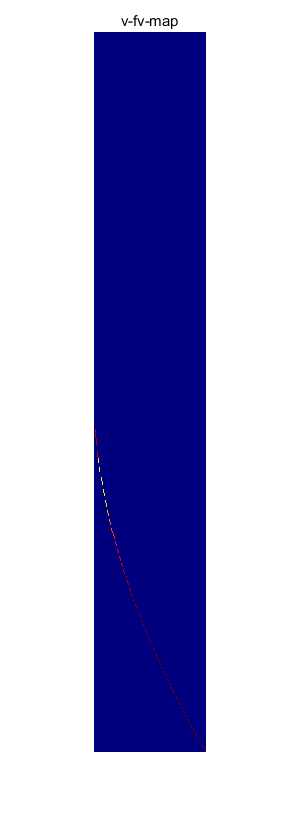

% 图4 v-fv曲线图


for i = 1: v_max
    for j = 1: range(u_max)
        if flow_v(i, j) + i > v_max
            flow_v(i, j) = 0;
        end
    end
end

 
v_fv_map = zeros(v_max, round(max(flow_v,[],'all')));
for i = 1:v_max
    for j = 1:u_max
        fv_id= round(flow_v(i, j));
        if fv_id >0 
             v_fv_map(i, fv_id) = v_fv_map(i, fv_id)+1;
        end
       
    end
end

fig4 = figure;
imshow(v_fv_map, [], 'Colormap', jet(4096));
title("v-fv-map")
axis off

addToolbarExplorationButtons(gcf)

% v-fv公式计算图 

% fv = Zd(v1-v0)/(hf/(v1-v0)-Zd)
% Y = Zd*X^2 / (hf - Zd*X)
% f = fx = fy = image_w / 2.0
% h = 2.4


v1 = 1:0.1:v_max;
v1 = v1(v1 - double(v0) > 0);

%选取中间非零点
v_head = v0;
v_tail = v_max;
for i = int32(round(v0) + 1) : v_max
    [~,max_index]=max(v_fv_map(i, :));
    if max_index ~= 1
        v_head = i;
        break
    end
end

for i = v_head : v_max
    [~,max_index]=max(v_fv_map(i, :));
    if max_index == 1
        v_tail = i + 1;
        break
    end
end


% 曲线拟合
fo = fitoptions('Method','NonlinearLeastSquares',...
               'Lower',[0],...
               'Upper',[1],...
               'StartPoint',[0.01]);
f=fittype('a*(x - 540) ^ 2 ','independent','x', ...
            'coefficients',{'a'},'options',fo);
x=v_head:v_tail;  x=x';
[~,max_index]=max(v_fv_map,[],2);
y=max_index(v_head:v_tail);

cfun=fit(x,y,f)

cfun =      General model:
     cfun(x) = a*(x - 540) ^ 2
     Coefficients (with 95% confidence bounds):
       a =   0.0005925  (0.0005911, 0.0005939)

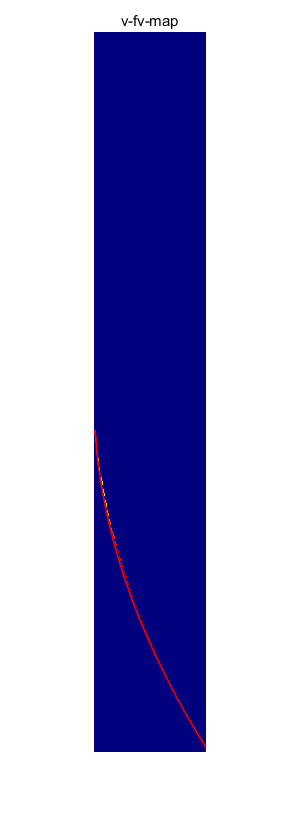

hold on
Y=cfun(x);
plot(Y, x, 'r','LineWidth',1)